# ENME 303 Lab 9

clear; clc; close all;
load accidents.mat
format long

fatalities = hwydata(:,4);
population = hwydata(:,14);


scatter(population,fatalities,"DisplayName","Measured Data")
xlabel("Population")
ylabel("Number of fatalities")
title("Fatalities vs total population by state")

x = population;
y = fatalities;

Phi = [x ones(length(x),1)];
Theta = inv(transpose(Phi)*Phi)*transpose(Phi)*y

Theta = 1.0e+02 *

   0.000001256394274
   1.427120171726537


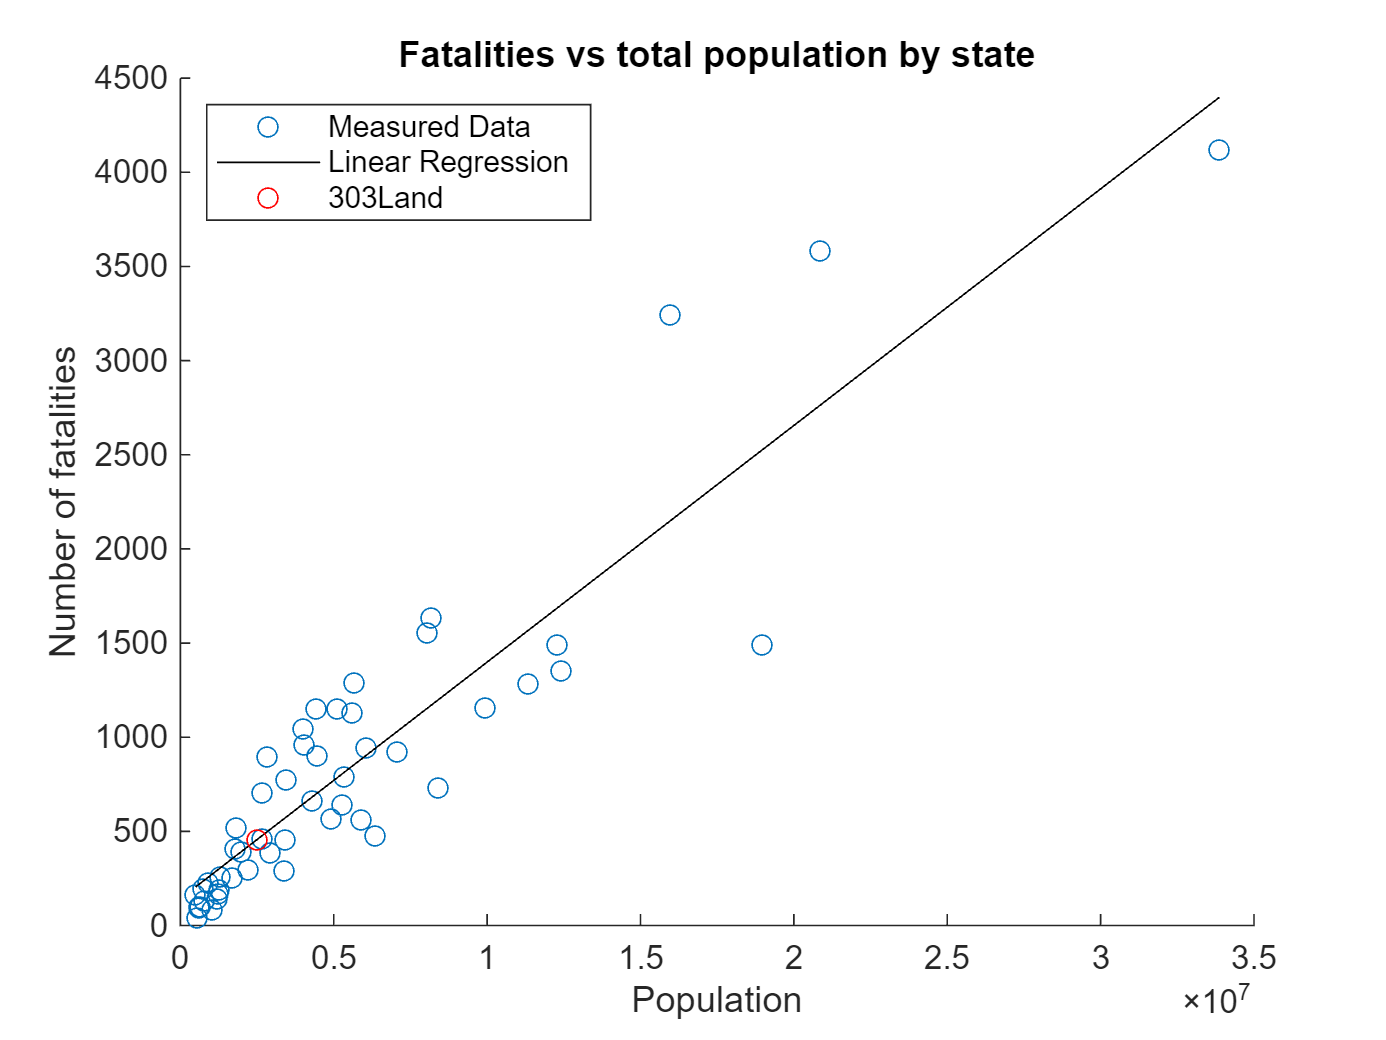

m = Theta(1);
c = Theta(2);

yCalc = m*x+c;

hold on;
plot(x,yCalc,'k',"DisplayName","Linear Regression")
legend("Location","northwest")

pop303Land = 2.5e6;
fatal303Land = m*pop303Land+c;
scatter(pop303Land,fatal303Land,"r","DisplayName","303Land")